# **4. Designing FIR filters using windows**

**4.1. Characteristics of window functions (use the fdatool) **

clear all; clc;

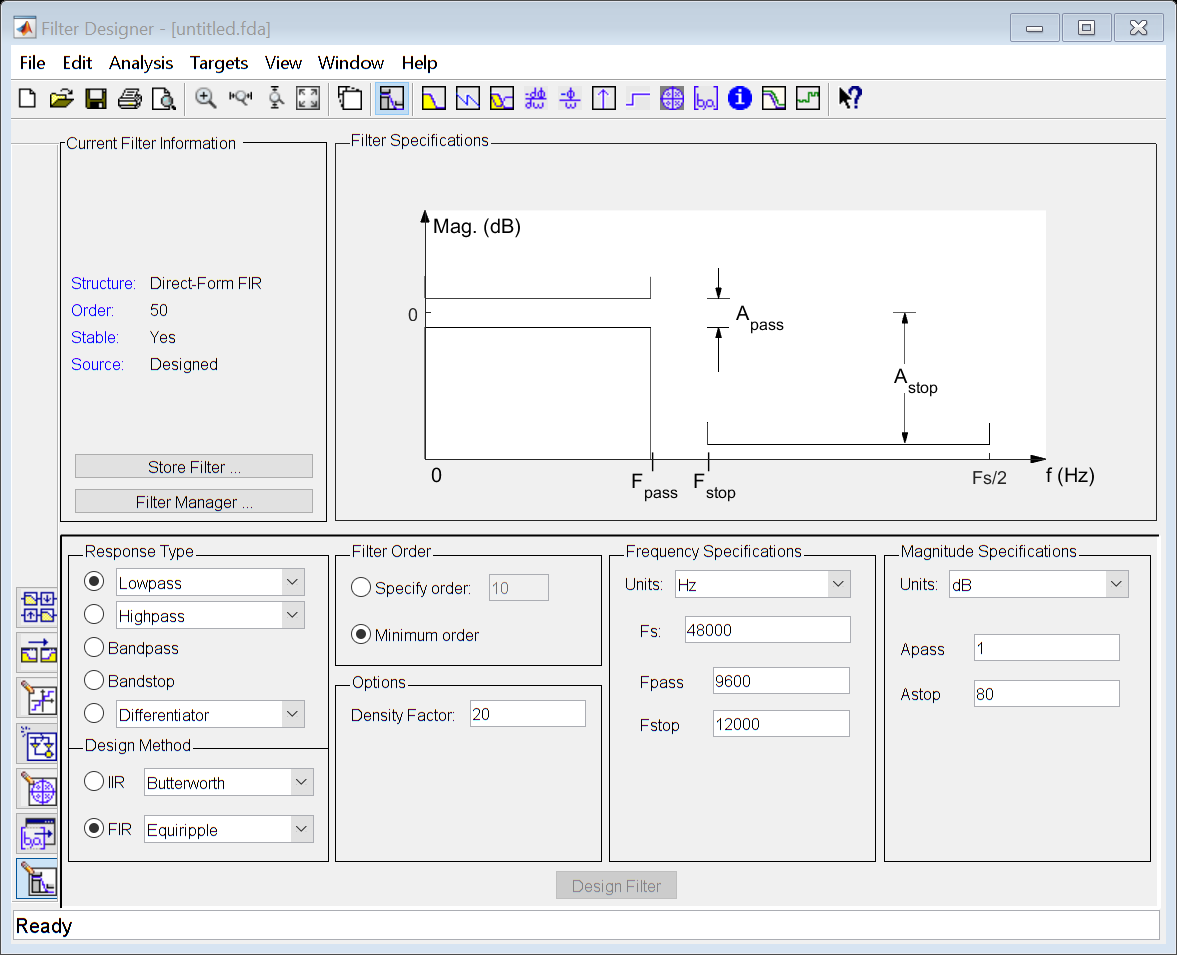

%filterDesigner tool has been used for obtaining the required charts
%fda files are attached with the folder
filterDesigner;

## Different Windows Functions

Creating different windows that filter order is 50  (size=51)

rectWin = rectwin(51);
hannWin = hann(51);
hammWin = hamming(51);
blacWin = blackman(51);

Plotting window functions

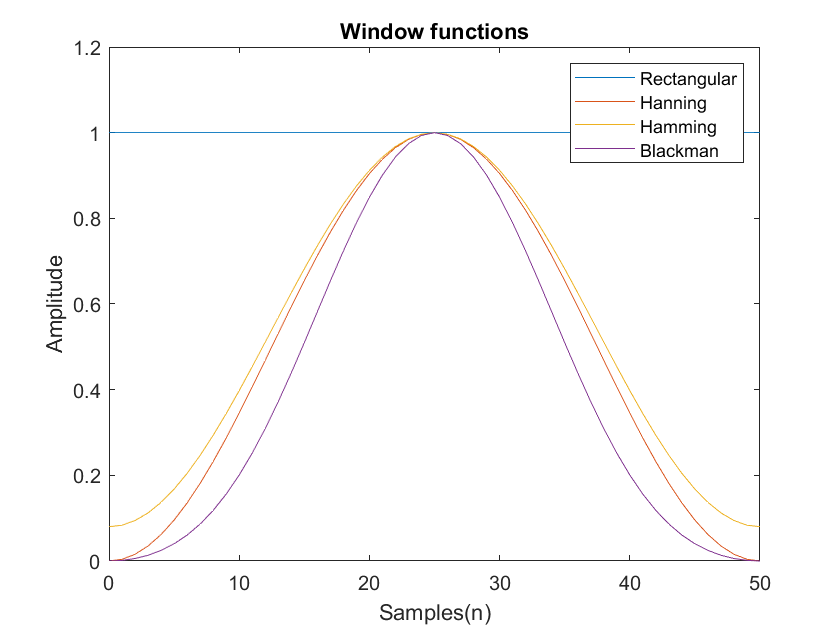

plot(0:50 , rectWin,0:50 , hannWin, 0:50 , hammWin,0:50 , blacWin);
title('Window functions');
ylim([0,1.2]);
legend('Rectangular' , 'Hanning' ,'Hamming' , 'Blackman');
xlabel('Samples(n)');
ylabel('Amplitude');

%filterDesigner tool has been used for obtaining the required charts
%fda files are attached with the folder
filterDesigner;

## 4.2. FIR Filter design and application using the Kaiser window 

Load the file

fs = 500;
load ECG_with_noise.mat;

Plotting the ECG signal

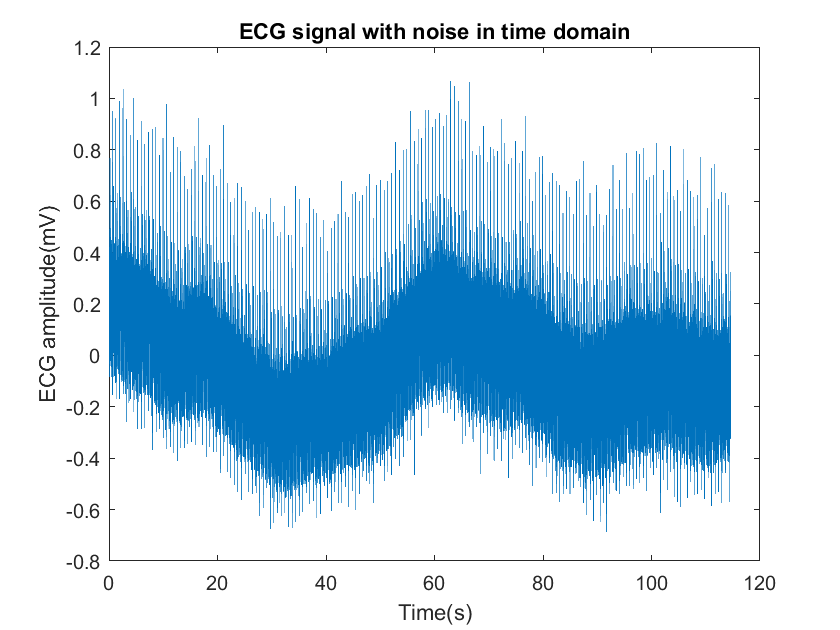

t = (1:length(nECG))/fs;
figure;
plot(t,nECG);
xlabel('Time(s)');
ylabel('ECG amplitude(mV)');
title('ECG signal with noise in time domain');

Plotting the Power Spectral Density of the Signal

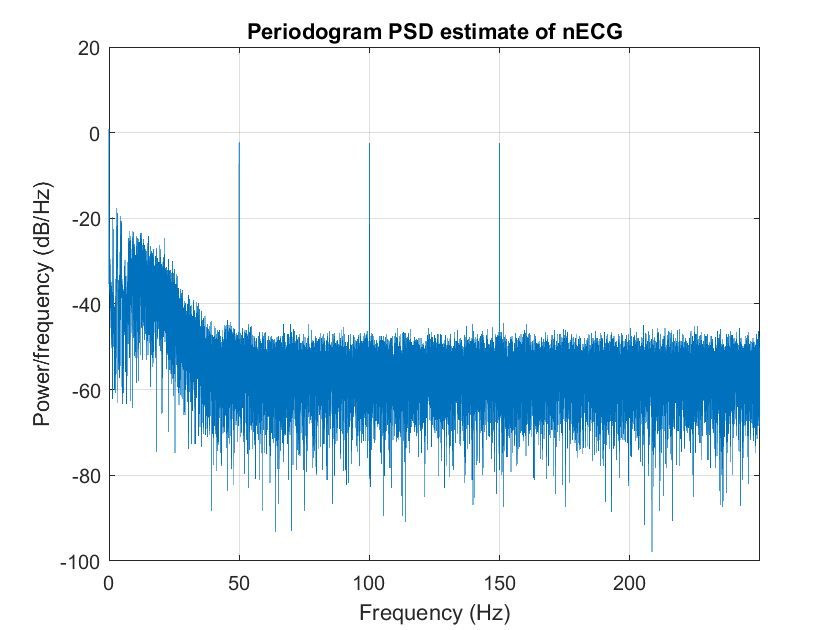

figure
periodogram(nECG,[],length(nECG),fs);
title('Periodogram PSD estimate of nECG');

**LPF parameter calculation**

lpass = 123;
lstop = 127;
delta = 0.001; 

lws = 2*pi*(lstop/fs);% stopband frequency (rad/s)
lwp = 2*pi*(lpass/fs);% passband frequency (rand/s)
lA  = -20*log10(delta); % minimum attenuation in the stopband OR maximum ripple in the passpand

ldw = lws - lwp;
lNtemp = ceil(((lA-8)/(2.285*ldw)) + 1);
lN = (rem(lNtemp,2) == 0) + lNtemp;  %if length is even add 1
lwc=(lws+lwp)/2;
lM = lN-1;

disp(lM);

   454



% as A>50 beta = 0.1102(A-8.7)
lbeta = 0.1102*(lA-8.7);
lIb = besseli(0, lbeta); % zeroth order modified Bessel function of the first kind

for n = 1:lM+1
    % Calculating coefficients Kaiser window w(n)
    lx = lbeta*sqrt(1-(((n-1)-lM/2)/(lM/2))^2);
    lI0 = besseli(0,lx);
    lw(n) = lI0/lIb;
    
    % Calculating coefficients of desired impulse response hd(n)
    if ((n-1)- (lM/2)) == 0 %n == M
        lhd(n) = lwc/pi;
    else 
        lhd(n) = sin(lwc*((n-1)-lM/2))/(pi*((n-1)-lM/2));
    end
end

% Calculating coefficients actual impulse response h(n)
lh = lhd.*lw;

Highpass filter calculation

hpass = 7; % passband frequency (rand/s)
hstop = 3; % stopband frequency (rad/s)
delta = 0.001;

hws = 2*pi*(hstop/fs);
hwp = 2*pi*(hpass/fs);
hA  = -20*log10(delta);% minimum attenuation in the stopband OR maximum ripple in the passpand

hdw = -hws + hwp;
hNtemp = ceil(((hA-8)/(2.285*hdw)) + 1);
hN = (rem(hNtemp,2) == 0) + hNtemp;  %if length is even add 1
hwc= (hws+hwp)/2;
hM = hN-1;

disp(hM);

   454



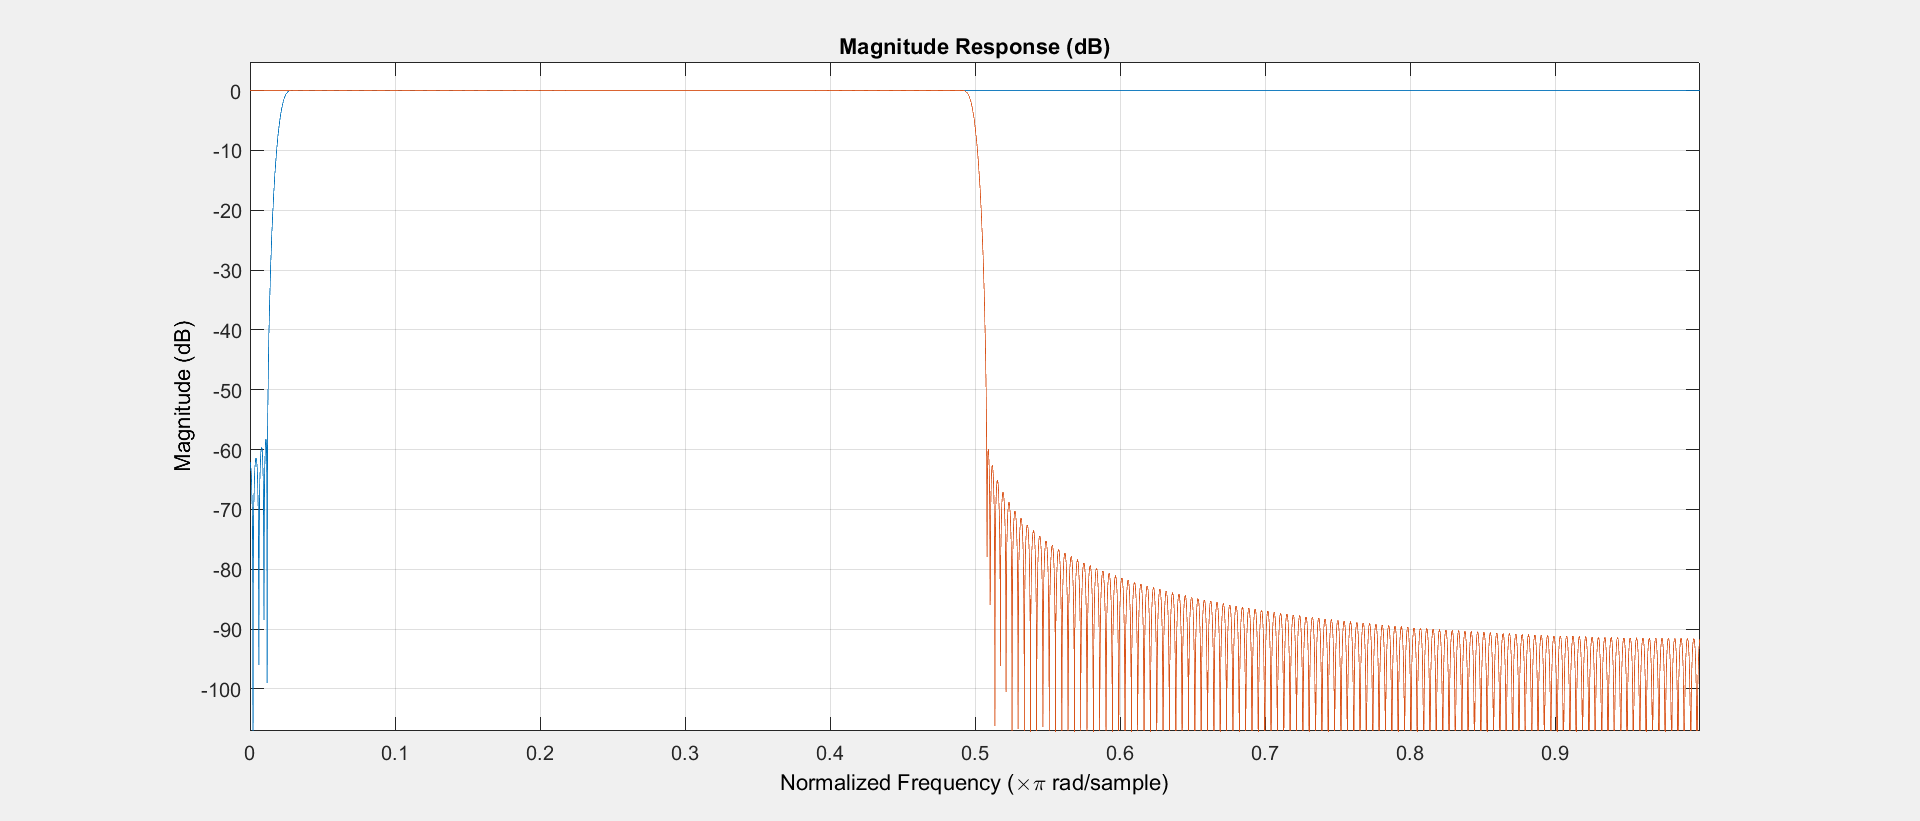

% as A>50 beta = 0.1102(A-8.7)
hbeta = 0.1102*(hA-8.7);
hIb = besseli(0, hbeta); % zeroth order modified Bessel function of the first kind

for n = 1:hM+1
    % Calculating coefficients Kaiser window w(n)
    hx = hbeta*sqrt(1-(((n-1)-hM/2)/(hM/2))^2);
    hI0 = besseli(0,hx);
    hw(n) = hI0/hIb;
    
    % Calculating coefficients of desired impulse response hd(n)
    if ((n-1)- (hM/2)) == 0 %n == M
        hd(n) = (pi - hwc)/pi;
    else 
        hd(n) = -1*sin(hwc*((n-1)-hM/2))/(pi*((n-1)-hM/2));
    end
end

% Calculating coefficients actual impulse response h(n)
hh = hd.*hw;
fvtool(hh,1,lh,1);

gdLow = round(grpdelay(lh,1 ,1));
gdHigh= round(grpdelay(hh,1 ,1));


Applying filters to the signal

**Low Pass Filter**

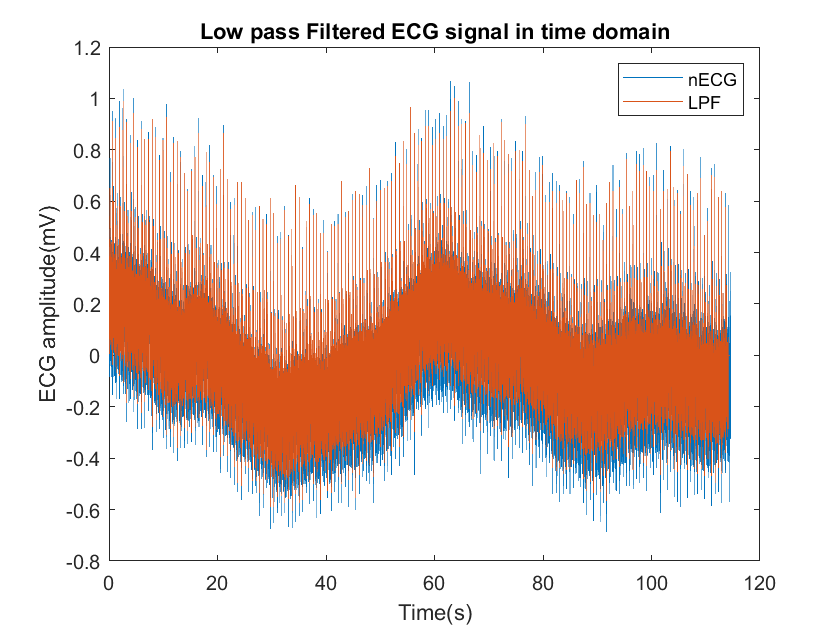

yLow = filter(lh,1,nECG);
yLow(1 : length(yLow)- round(gdLow)) = yLow(round(gdLow) + 1  : end);
yLow(length(yLow)- round(gdLow) + 1: end)=0;

%plot low pass filtered signal
figure;
plot(t,nECG,t,yLow);  %plot ECG signal
xlabel('Time(s)');
ylabel('ECG amplitude(mV)');
title('Low pass Filtered ECG signal in time domain');
legend('nECG' ,'LPF');

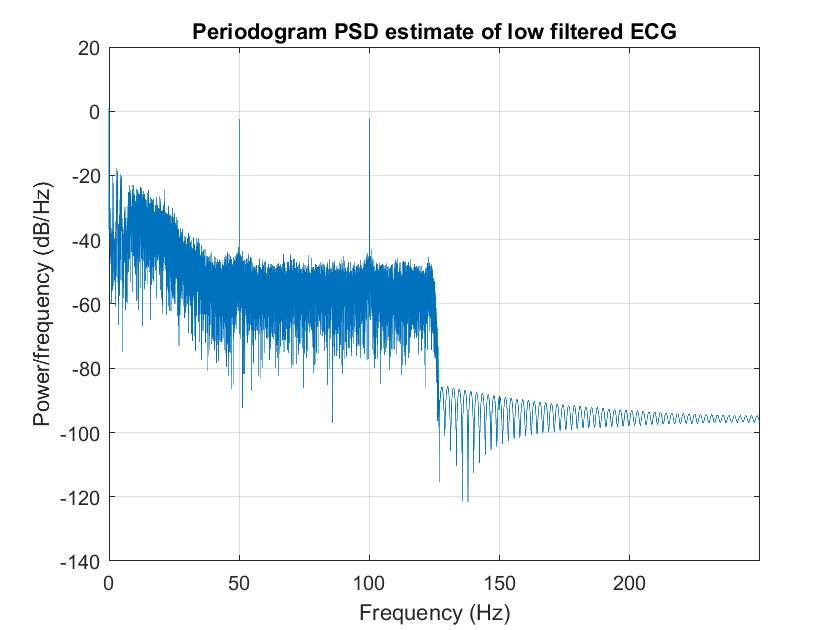

%plot low pass filtered signal PSD
figure;
periodogram(yLow,[],length(yLow),fs);
title('Periodogram PSD estimate of low filtered ECG');

**High Pass Filter**

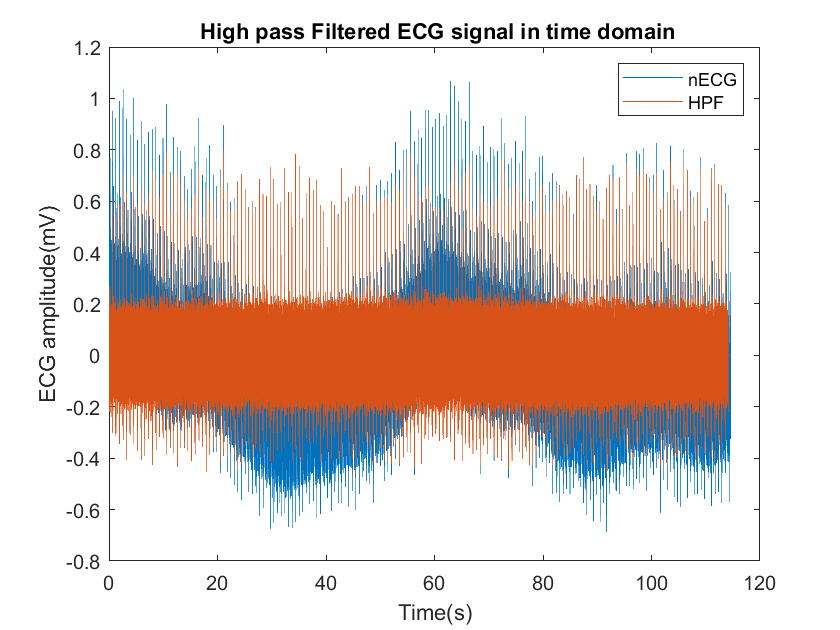

yHigh = filter(hh,1,yLow);
yHigh(1 : length(yHigh)- round(gdHigh)) = yHigh(round(gdHigh) + 1  : end);
yHigh(length(yHigh)- round(gdHigh) + 1: end)=0;

%plot high pass filtered signal
figure;
plot(t,nECG,t,yHigh);  %plot ECG signal
xlabel('Time(s)');
ylabel('ECG amplitude(mV)');
title(' High pass Filtered ECG signal in time domain');
legend('nECG' ,'HPF');

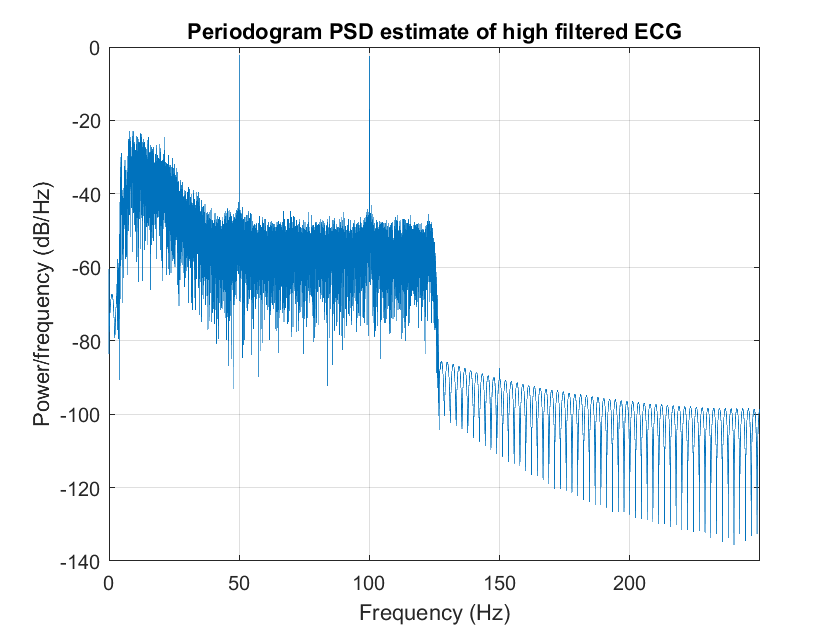


%plot low pass filtered signal PSD
figure;
periodogram(yHigh,[],length(yHigh),fs);
title('Periodogram PSD estimate of high filtered ECG');

High and Low pass Filter

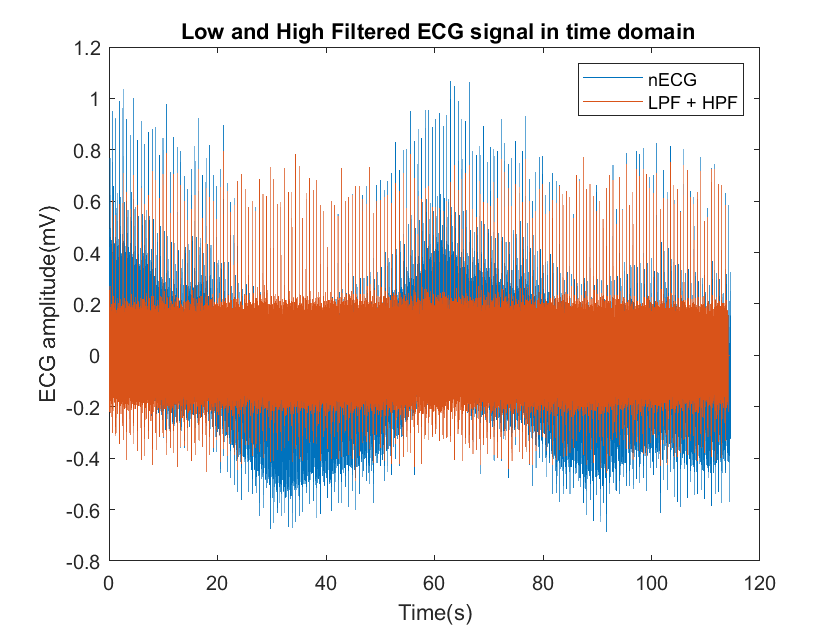

yHigh = filter(hh,1,yLow);
yHigh(1 : length(yHigh)- round(gdHigh)) = yHigh(round(gdHigh) + 1  : end);
yHigh(length(yHigh)- round(gdHigh) + 1: end)=0;

%plot low ,high filtered signal
figure;
plot(t,nECG,t,yHigh);  %plot ECG signal
xlabel('Time(s)');
ylabel('ECG amplitude(mV)');
title(' Low and High Filtered ECG signal in time domain');
legend('nECG' ,'LPF + HPF');

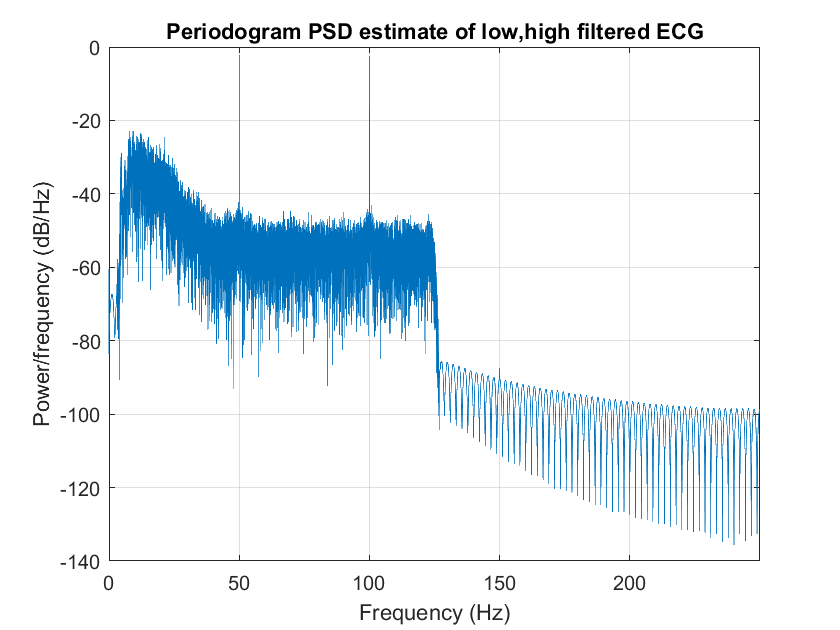


figure
periodogram(yHigh,[],length(yHigh),fs);
title('Periodogram PSD estimate of low,high filtered ECG');

**Comb filter**

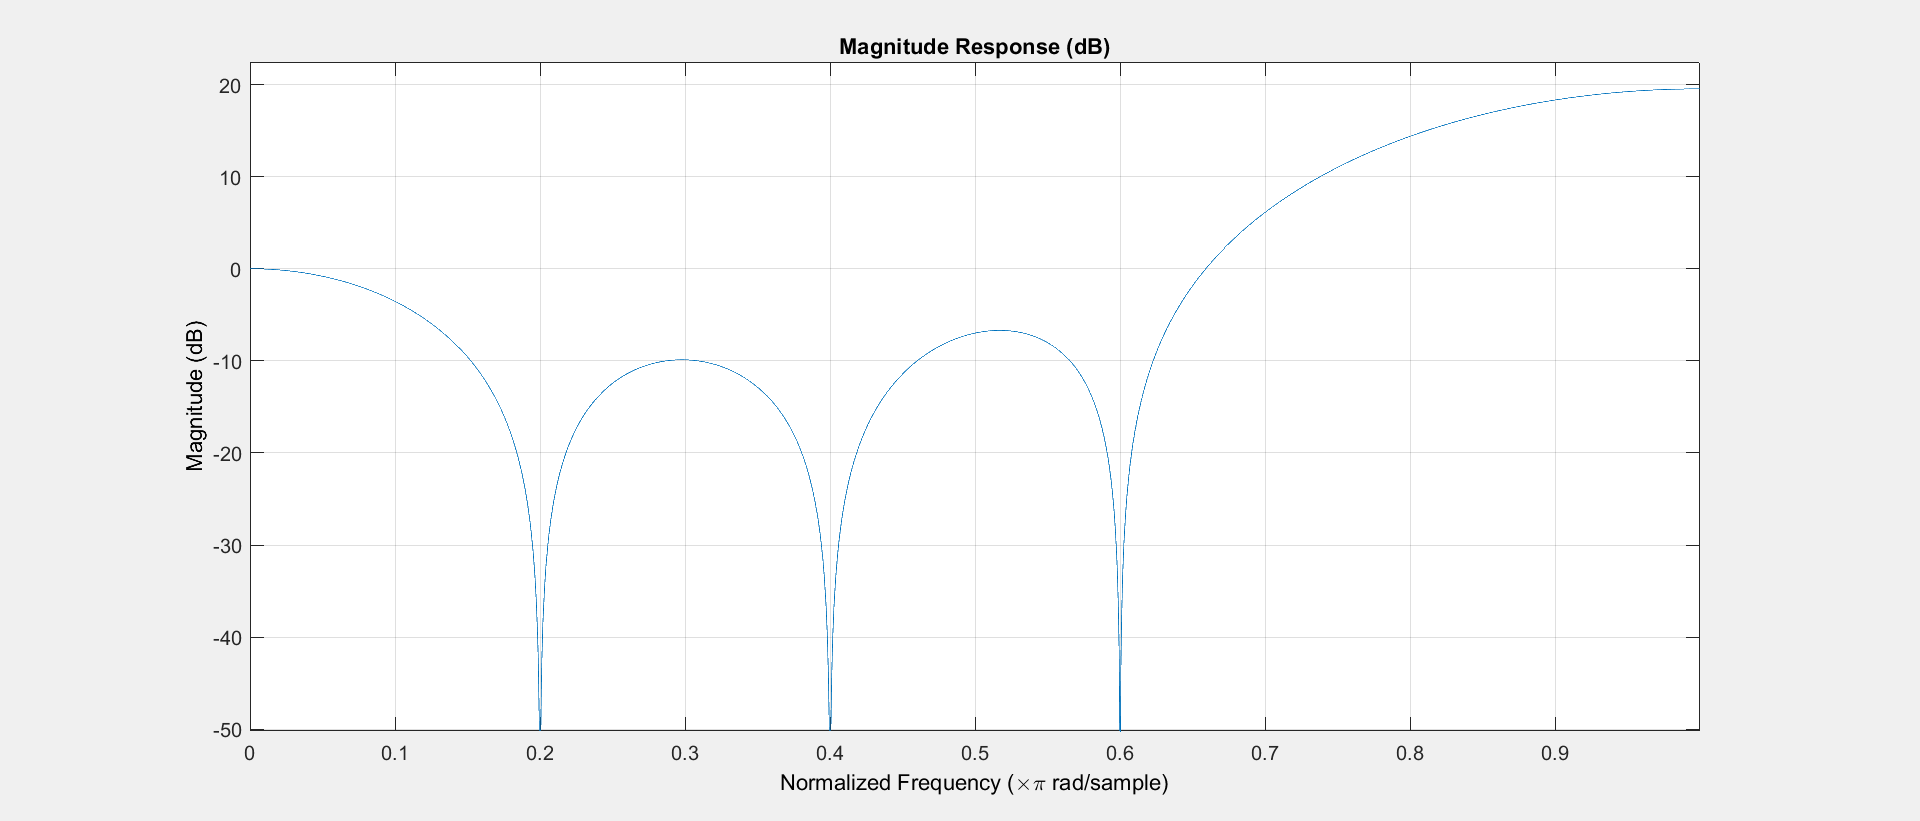

%Comob filter design
comb1 = 50;
comb2 = 100;
comb3 = 150;

wComb1 = (comb1*2*pi)/fs;
wComb2 = (comb2*2*pi)/fs;
wComb3 = (comb3*2*pi)/fs;


%caluclate zeros
z1 = cos(wComb1) + 1i*sin(wComb1);
z1_c = cos(wComb1) - 1i*sin(wComb1);
z2 = cos(wComb2) + 1i*sin(wComb2);
z2_c = cos(wComb2) - 1i*sin(wComb2);
z3 = cos(wComb3) + 1i*sin(wComb3);
z3_c = cos(wComb3) - 1i*sin(wComb3);

%calculate polynomial coefficents
z1_conv = conv( [1 -z1] , [1 -z1_c]);
z2_conv = conv( [1 -z2] , [1 -z2_c]);
z3_conv = conv( [1 -z3] , [1 -z3_c]);
z12_conv = conv( z1_conv , z2_conv);
z123_conv = conv( z12_conv , z3_conv);
z_123_conv_flip=flip(z123_conv , 7);
 
%calculate polynomial gain
G = 1/polyval(z123_conv,1);

comb = z123_conv*G;

%visulaize comb filter
fvtool(comb,1);

**LOW + HIGH + COMB**

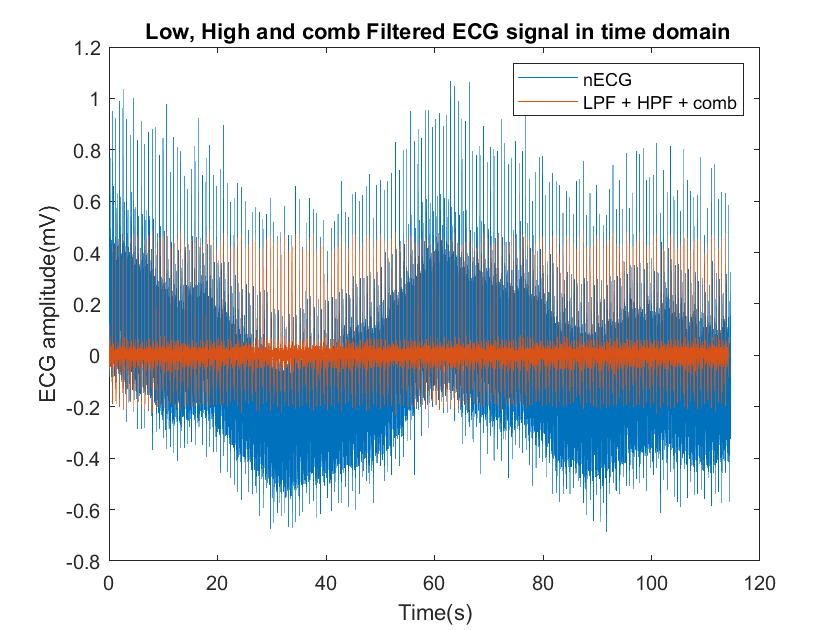

yFiltered = filter(comb , 1 ,yHigh);
%plot filtered signal
figure;
plot(t ,nECG , t,yFiltered);  %plot ECG signal
xlabel('Time(s)');
ylabel('ECG amplitude(mV)');
title(' Low, High and comb Filtered ECG signal in time domain');
legend('nECG' ,'LPF + HPF + comb');

**Power Spectral Density of filterered signal **

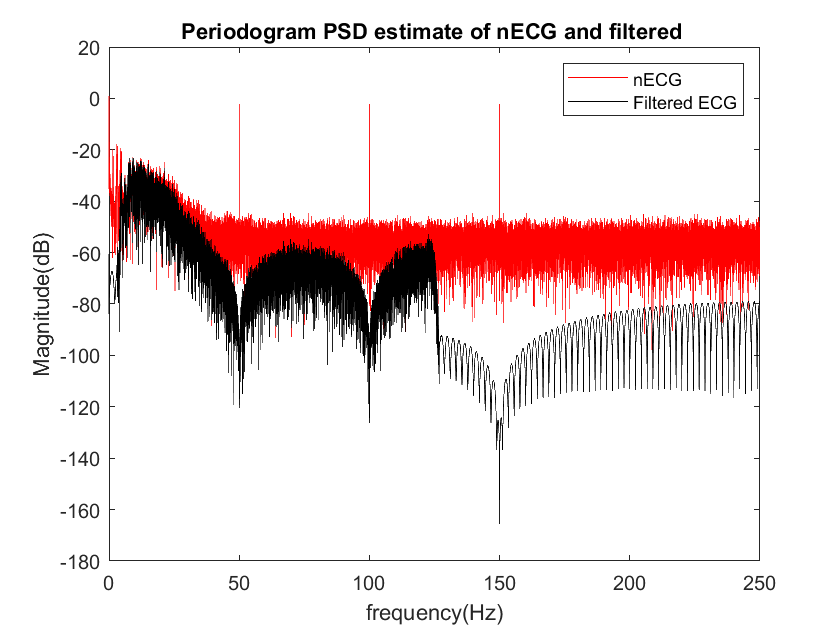

figure;

%extract PSD data of noisy and filter output
[psd1,w1] = periodogram(nECG,[],length(nECG),fs);
[psd2,w2] = periodogram(yFiltered,[],length(yFiltered),fs);

%plot PSD of noisy and filtered signal
plot(w1,10*log10(psd1) , 'r',w2,10*log10(psd2) , 'black')
title('Periodogram PSD estimate of nECG and filtered ');
xlabel('frequency(Hz)');
ylabel('Magnitude(dB)');
legend('nECG', 'Filtered ECG');

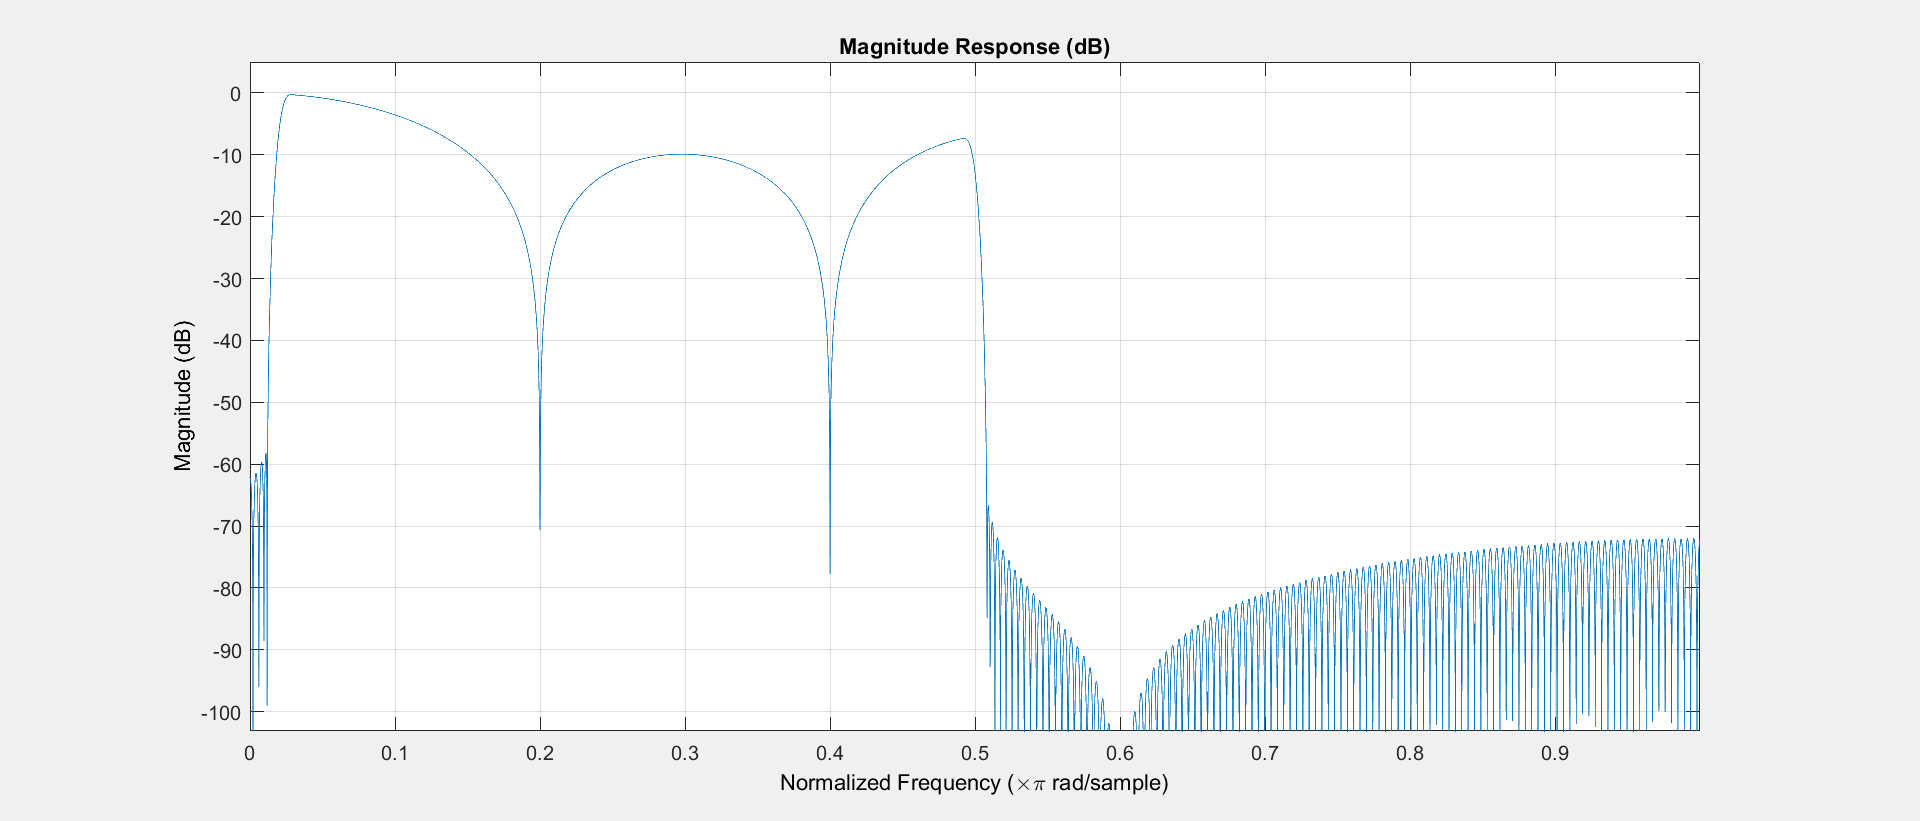


%visulaize combinede filter
cascade  = conv(conv(lh ,hh), comb);
fvtool(cascade,1);